# Testing different models individually and comparing

## Setting up the signal

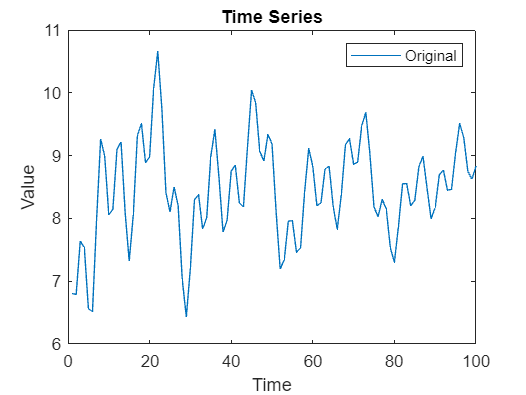

clear all;

addpath('./tensorlab/');

N = 100;
t = (1:N)';

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Signal multiplicator
smul = 40*rand();

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * smul * 0.1 * t);
base_signal2 = sin(2 * pi * smul * 0.05 * t);
base_signal3 = sin(2 * pi * smul * 0.02 * t);

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

time_series = signal1+signal2+signal3;

% Plot the time series
figure;
plot(time_series);
legend({"Original"})
title('Time Series');
xlabel('Time');
ylabel('Value');

## AR vs SVD

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_svd(training_series,num_predict,optimal_order,components);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.239511119489282


rmse(predictions_other,ground_truths,2)

ans =    0.029116293527303


## AR vs CPD mean sum

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_ms(training_series,num_predict,optimal_order,components);

end
disp("done!");

rmse(predictions_full,ground_truths,2)
rmse(predictions_other,ground_truths,2)

## AR vs CPD mean full


num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_mf(training_series,num_predict,optimal_order,components,'M', 2);

end
disp("done!");

rmse(predictions_full,ground_truths,2)
rmse(predictions_other,ground_truths,2)

## AR vs CPD columns

num_experiments = 1;
components = 3;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_col(training_series,num_predict,10,components);

end
disp("done!");

rmse(predictions_full,ground_truths,2)
rmse(predictions_other,ground_truths,2)

## AR vs MLSVD

num_experiments = 1;
reduction = 0.2;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_mlsvd(training_series,num_predict,10,reduction,'L',10);

end

iter 1


    "Dimension of hankel: 10"    "Dimension of hankel: 33"    "Dimension of hankel: 58"



disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.338820308921632


rmse(predictions_other,ground_truths,2)

ans =    0.415103977966339


## AR vs SVD (segmentation)

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_svd(training_series,num_predict,optimal_order,components,'embedding', 2);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.337200919226603


rmse(predictions_other,ground_truths,2)

ans =    0.120144798646342
